# Signal Processing with MATLAB

*This lecture is partly adapted from MATLAB online tutorial.*

## Signal Processing Toolbox

[https://www.mathworks.com/products/signal.html](https://www.mathworks.com/products/signal.html)

Signal Processing Toolbox™ provides functions and apps to analyze, preprocess, and extract features from uniformly and nonuniformly sampled signals. 

It provides tools and algorithms for:

- filter design and analysis

- resampling, smoothing, detrending

- power spectrum estimation

- extracting features like changepoints and envelopes

- finding peaks and signal patterns

- quantifying signal similarities

- performing measurements such as SNR and distortion

- ... ...

### Signal processing pipeline

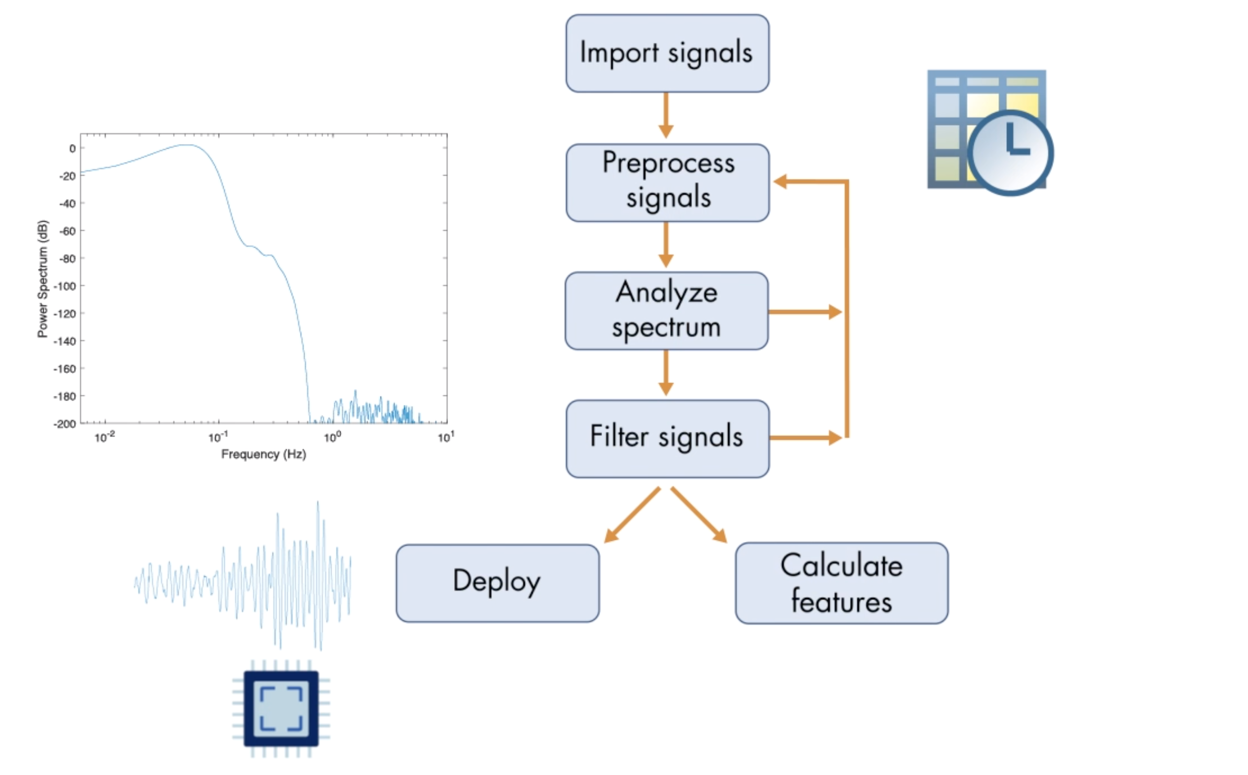

## Signal processing methods for spectral analysis

**Earthquak data (December 26, 2004, Indonesia)**

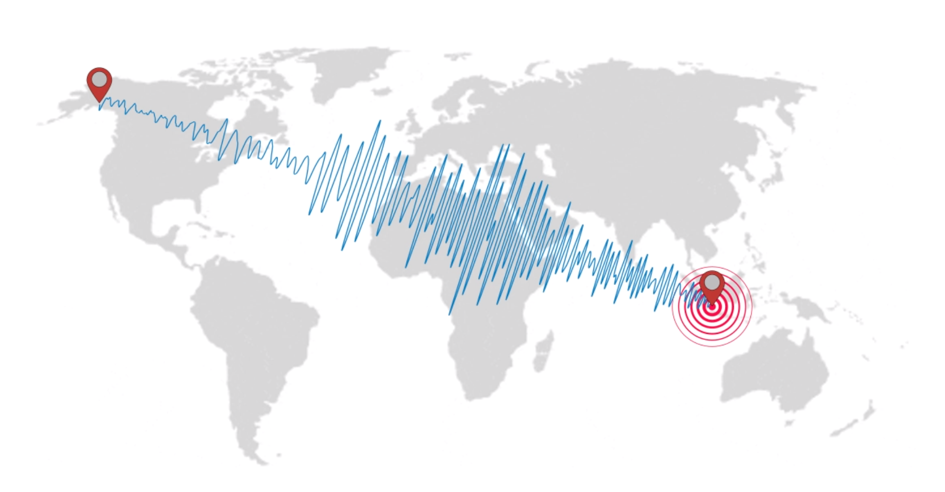

The vibrations travel all the way to Alaska, and are picked up by three seismic stations.

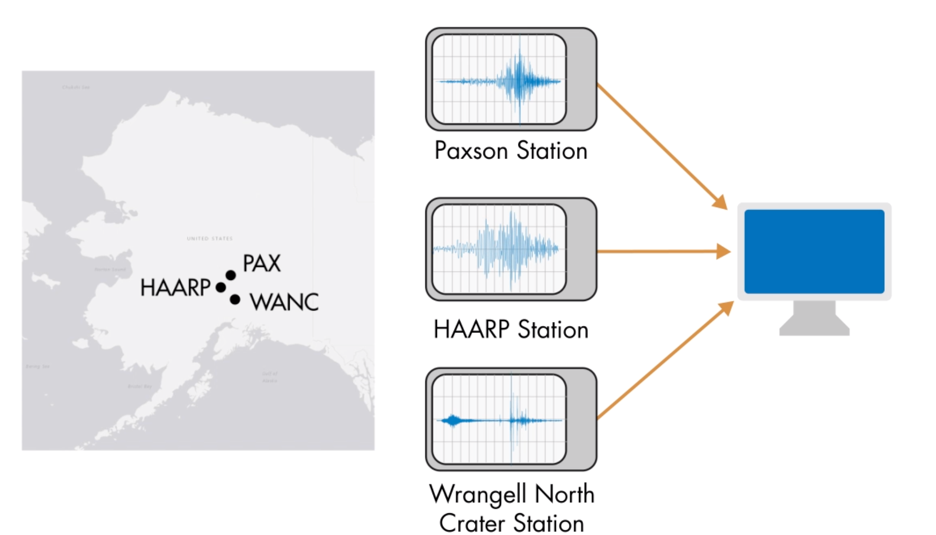

### Load and display signals

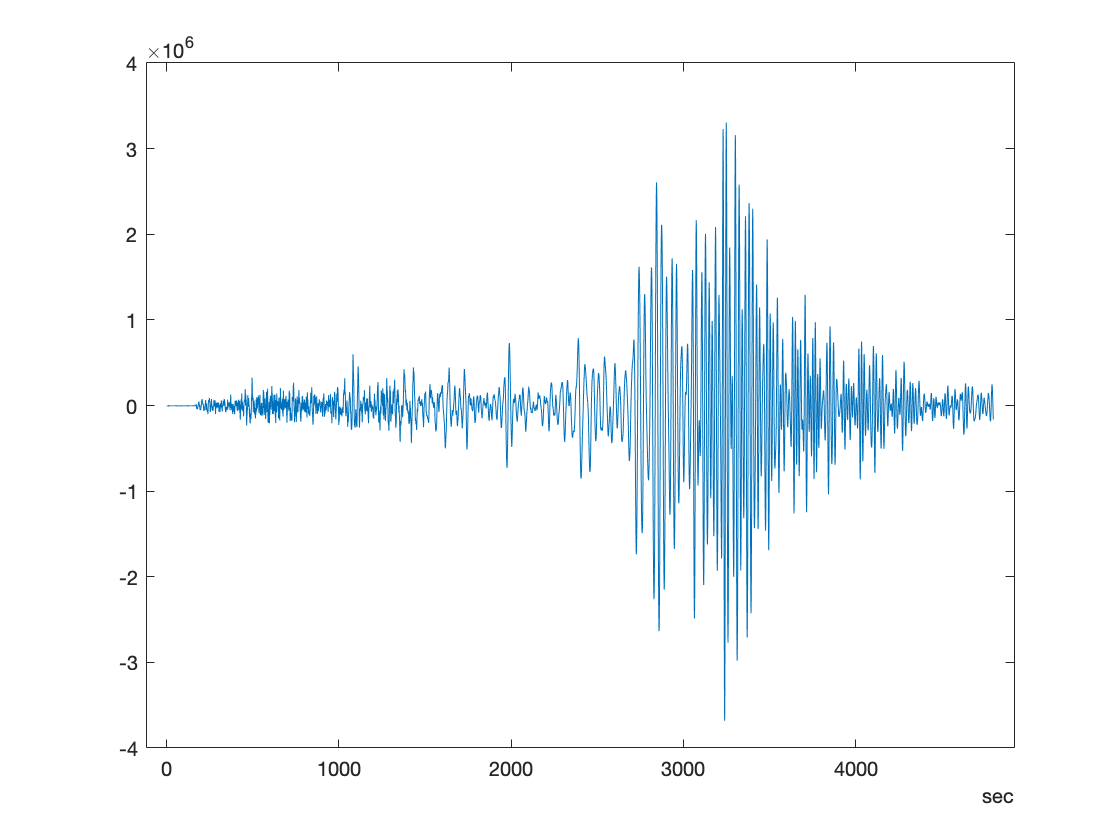

Ts = readmatrix("data/seismicstation_ts.csv");
harp = readtimetable("data/harp.csv","SampleRate",1/Ts(1));
plot(harp.Time,harp.Signal)

### Basic preprocessing 

Initial preprocessing could include:

- Normalizing

- Resampling

- Aligning

Extract a region of the HARP signal.

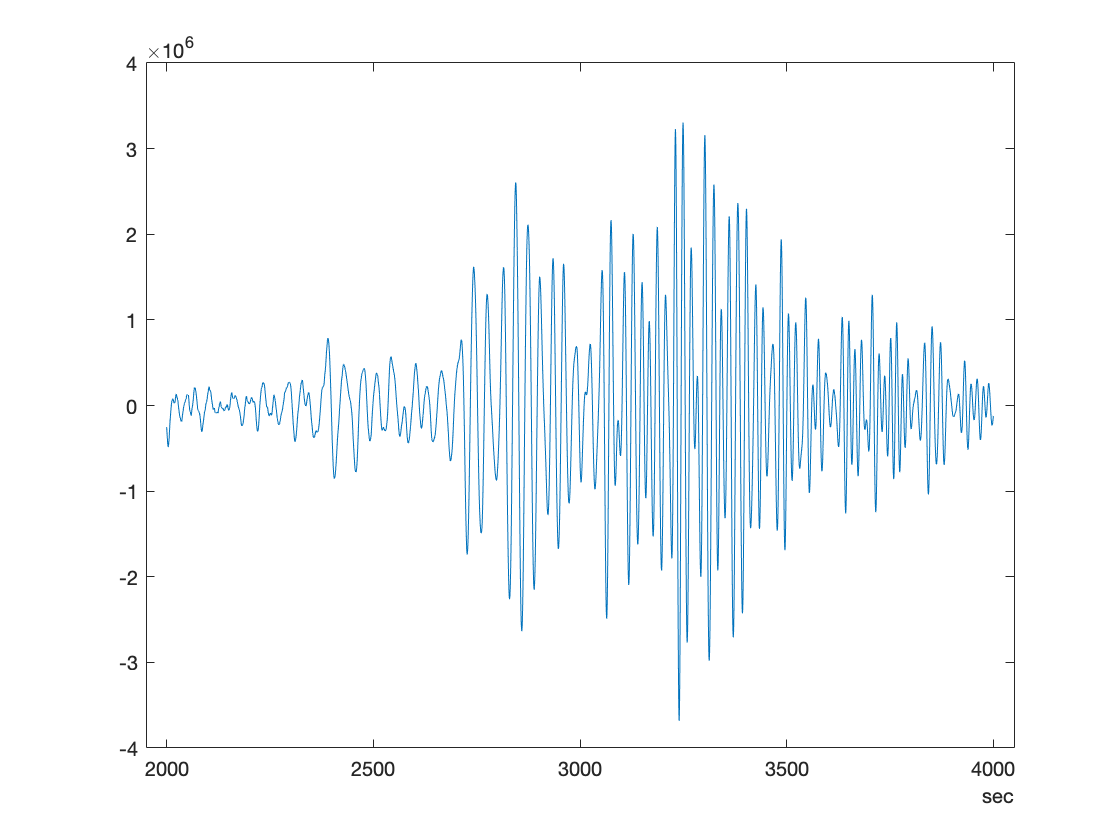

tstart = seconds(2000);
tend = seconds(4000);
timeLimits = timerange(tstart,tend);
harp = harp(timeLimits,:);
plot(harp.Time,harp.Signal)

### Power spectrum

View the frequency content of a signal by calculating the power spectrum with the `pspectrum` function.

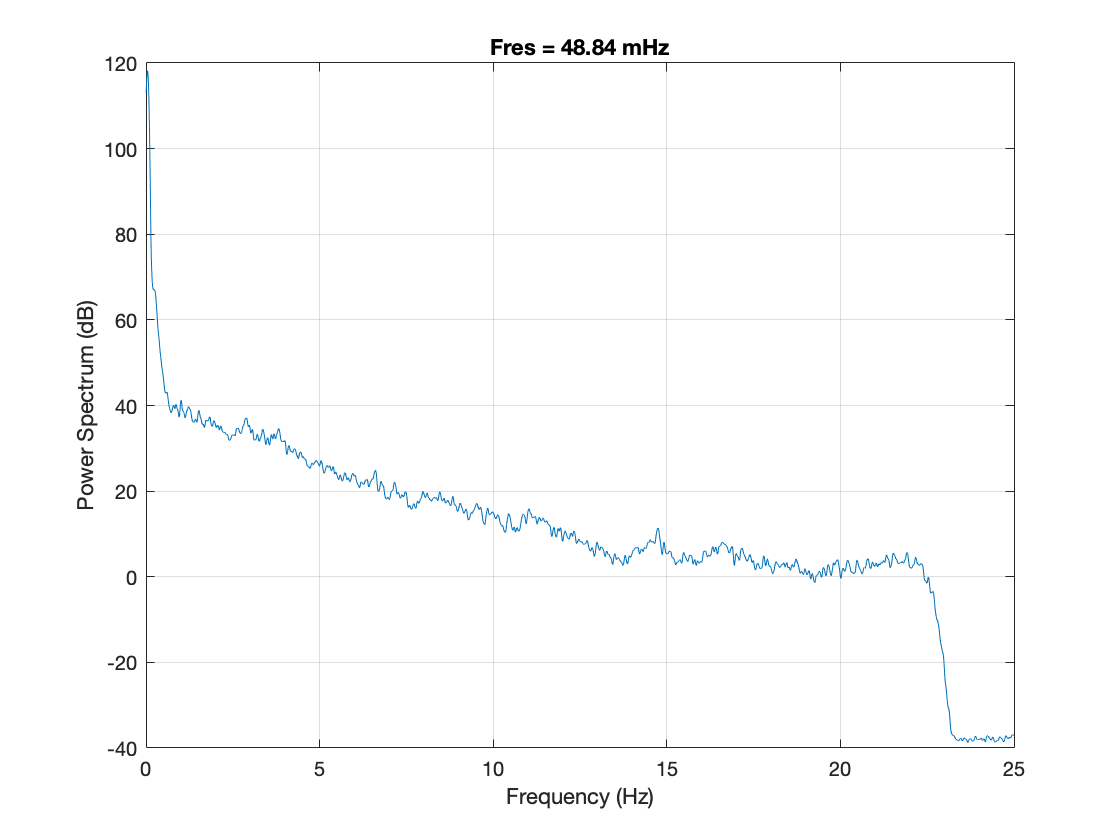

pspectrum(harp)

Zoom in on the meaningful seismic activity by setting the frequency limits while calculating the power spectrum.

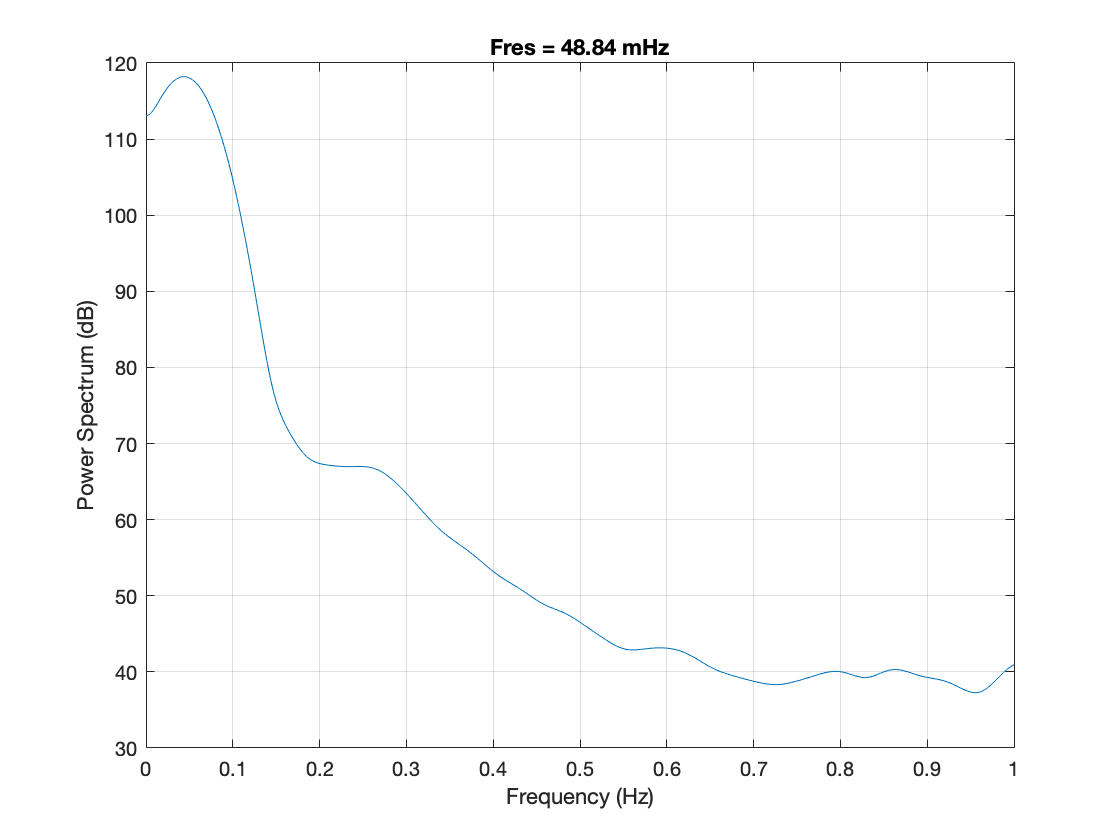

pspectrum(harp,"FrequencyLimits",[0 1])

### Compare signals

Compare the seismic signals from the HARP, PAX, and Mt Wrangell stations.

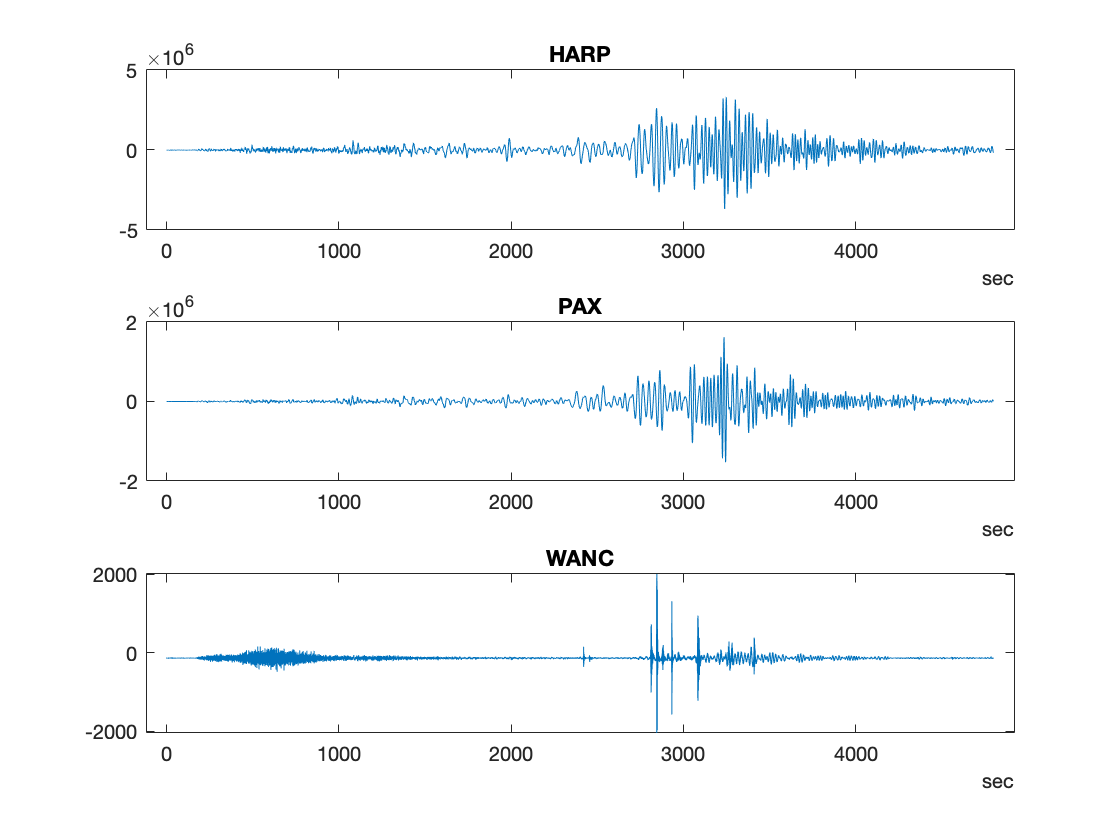

harp = readtimetable("data/harp.csv","SampleRate",1/Ts(1));
pax = readtimetable("data/pax.csv","SampleRate",1/Ts(2));
wanc = readtimetable("data/wanc.csv","SampleRate",1/Ts(3));

subplot(3,1,1)
plot(harp.Time,harp.Signal)
title("HARP")

subplot(3,1,2)
plot(pax.Time,pax.Signal)
title("PAX")

subplot(3,1,3)
plot(wanc.Time,wanc.Signal)
title("WANC")

Compare the frequency content.

quakes = synchronize(harp,pax);
head(quakes)

ans = 8×2 timetable
      Time      Signal_harp    Signal_pax
    ________    ___________    __________

    0 sec          -3094          389    
    0.02 sec       -3108          391    
    0.04 sec       -3126          402    
    0.06 sec       -3149          407    
    0.08 sec       -3172          409    
    0.1 sec        -3204          417    
    0.12 sec       -3242          420    
    0.14 sec       -3282          424    


head(wanc)

ans = 8×1 timetable
      Time      Signal
    ________    ______

    0 sec        -142 
    0.01 sec     -138 
    0.02 sec     -140 
    0.03 sec     -144 
    0.04 sec     -140 
    0.05 sec     -139 
    0.06 sec     -141 
    0.07 sec     -139 


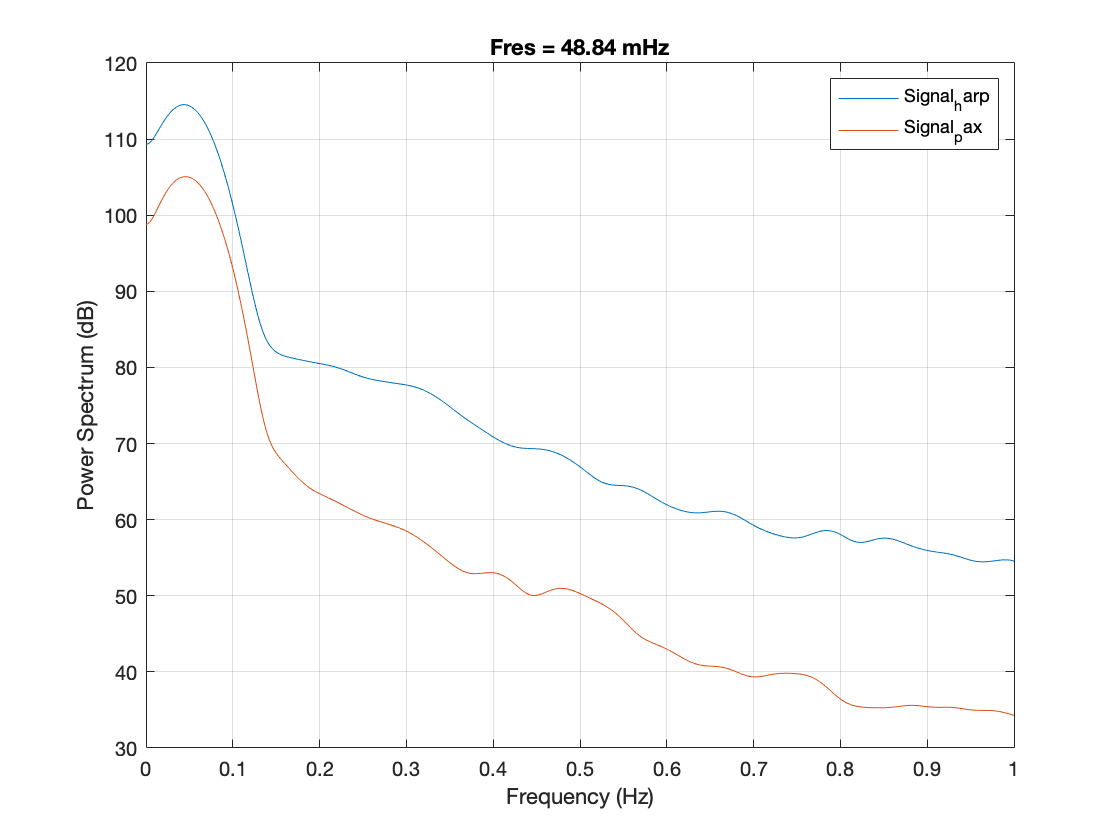

figure
pspectrum(quakes,"FrequencyLimits",[0 1])
legend(quakes.Properties.VariableNames)

### Cleaning up signals

Resample `wanc` to match the sample rate for `harp` and `pax`.

The seismic signals are all uniformly sampled, so here we only need to provide the signal and resample factors, `p` and `q`. 

`y` `=` `resample``(``x``,``p``,``q``)`

`p` and `q` are integer resample factors. The output signal `y` has `p/q` samples from `x`.

wanc = resample(table2array(wanc),1,2);
wanc = array2timetable(wanc,'SampleRate',1/Ts(3)*1/2,'VariableNames',{'Signal'})

wanc = 240000×1 timetable
      Time      Signal 
    ________    _______

    0 sec       -105.05
    0.02 sec    -149.89
    0.04 sec    -136.71
    0.06 sec    -141.92
    0.08 sec     -141.2
    0.1 sec     -141.55
    0.12 sec     -138.6
    0.14 sec    -140.21
    0.16 sec    -142.53
    0.18 sec    -139.62
    0.2 sec      -133.1
    0.22 sec    -140.89
    0.24 sec    -141.44
    0.26 sec    -138.09
    0.28 sec    -136.64
    0.3 sec     -141.46


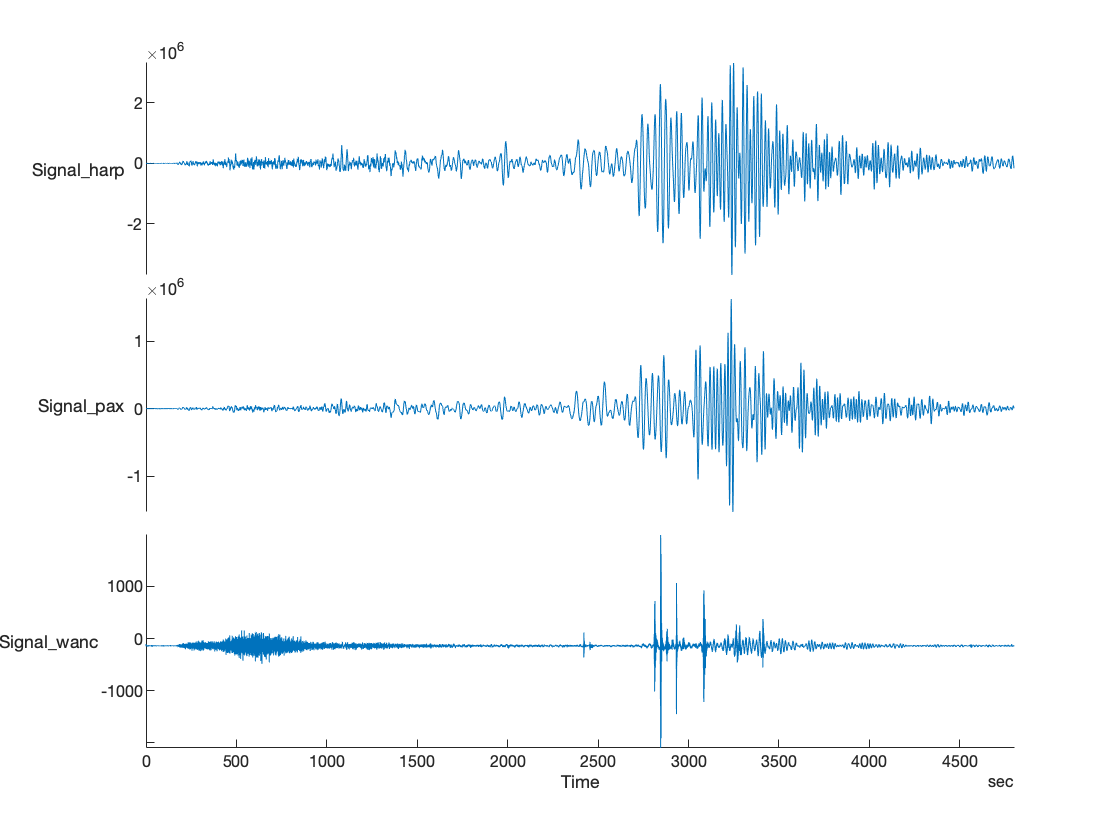

quakes = synchronize(harp,pax,wanc);
stackedplot(quakes);

The HARP and PAX signals are much larger than the Mount Wrangell signal. It will be easier to compare the signals if they're all normalized. 

harp = normalize(harp);
pax = normalize(pax);
wanc = normalize(wanc);
quakes = synchronize(harp,pax,wanc);

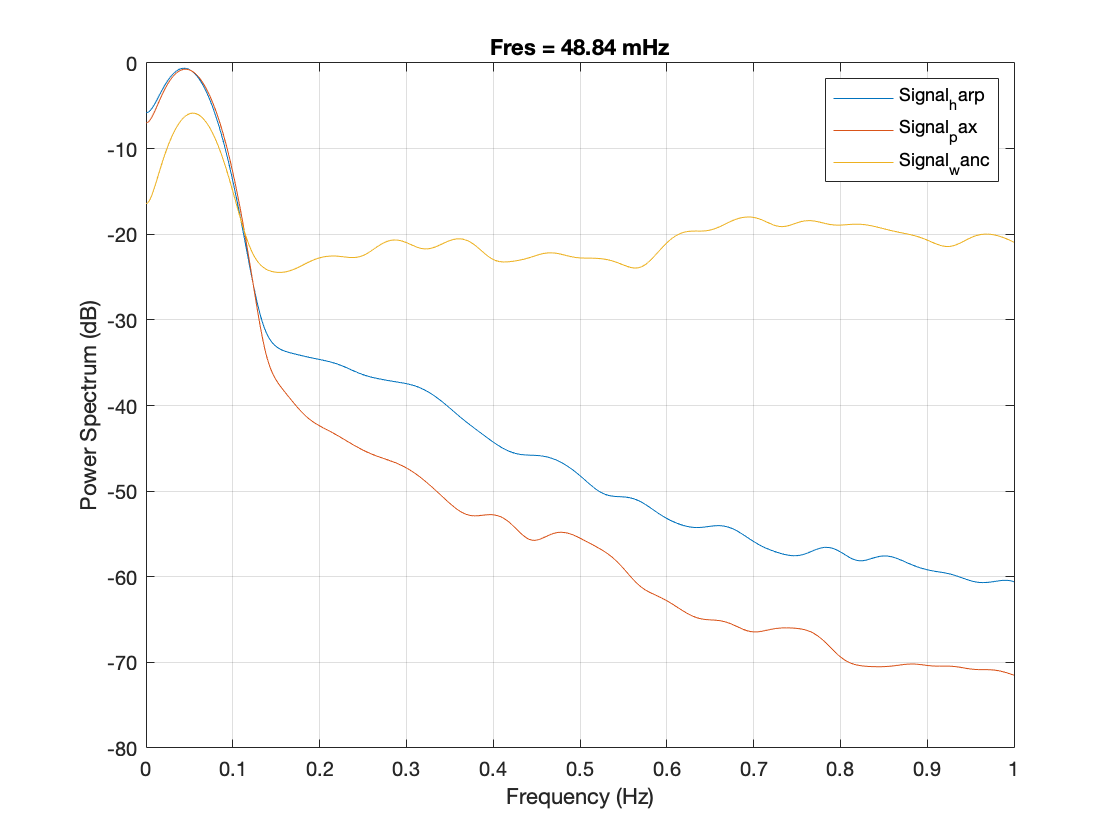

figure
pspectrum(quakes,"FrequencyLimits",[0 1])
legend(quakes.Properties.VariableNames);

### Aligning signals

The seismic stations are located in different places in Alaska. As the surface waves traveled from Indonesia, they arrived at the seismic stations at different times. The distance between stations caused a lag between the recorded waves.

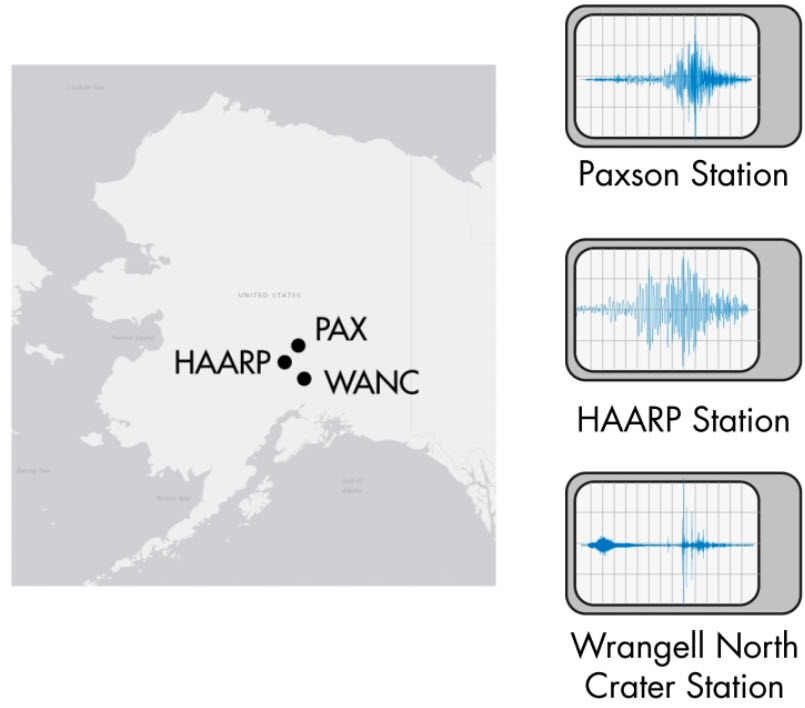

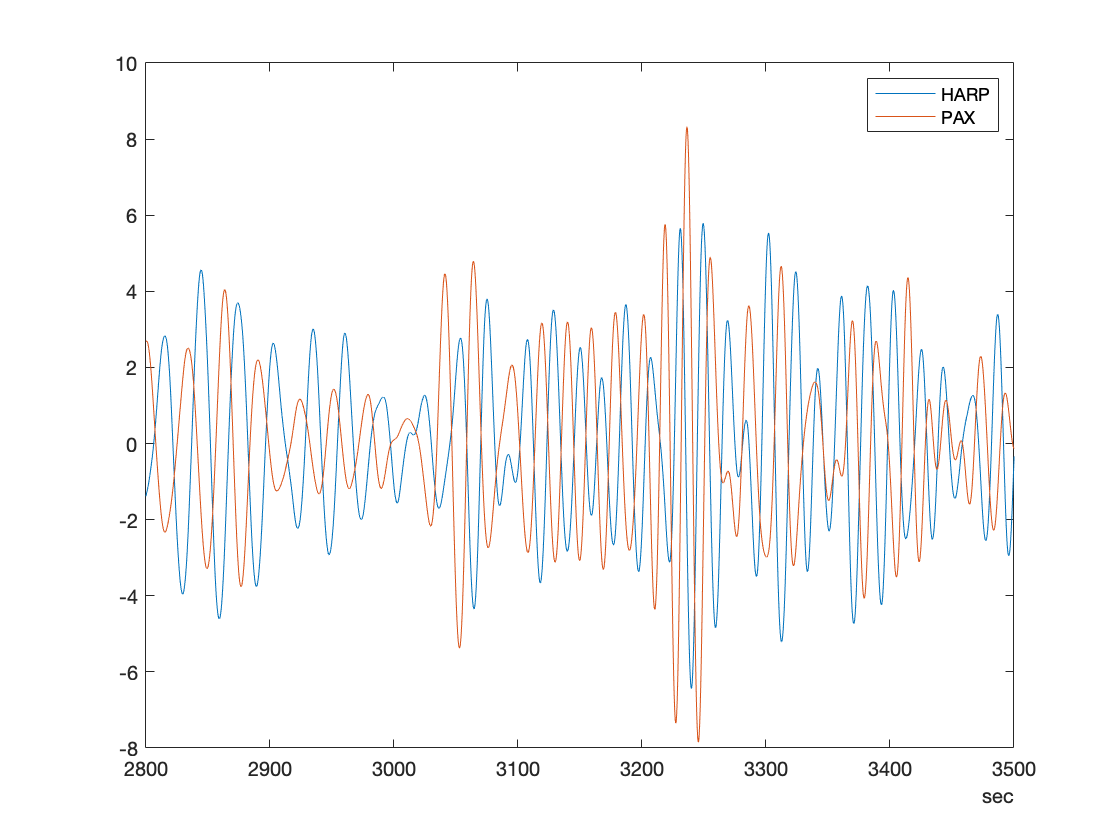

clf
plot(harp.Time,harp.Signal)
hold on
plot(pax.Time,pax.Signal)
hold off
legend("HARP","PAX")
xlim(seconds([2800 3500]))

**Cross-correlation** can be used to measure the similarity between a signal and a shifted, or lagged, copy of that signal. Even though the HARP, PAX, and Mount Wrangell signals aren't copies of each other, all three seismometers should have picked up the same surface waves from the Sumatra earthquake.

Visualize cross-correlation using stem plots.

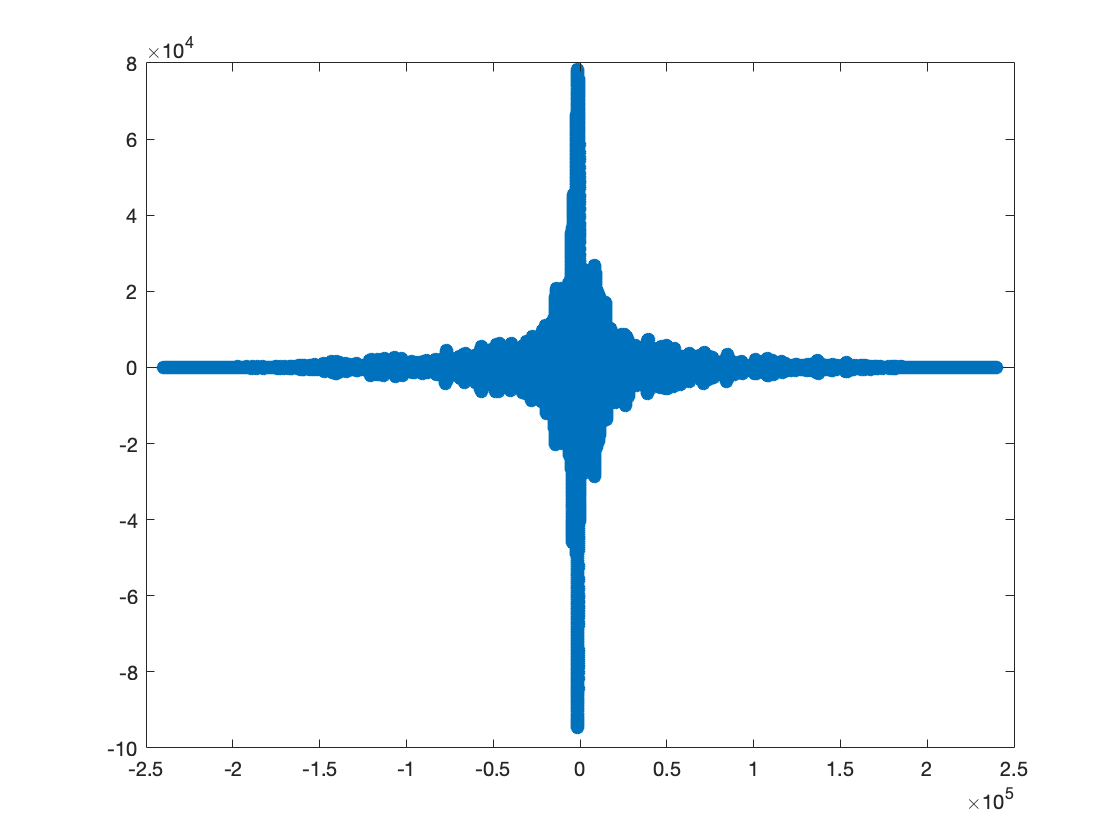

[c,lags] = xcorr(harp.Signal,wanc.Signal);
stem(lags,c)

The `finddelay` function uses cross-correlation to estimate the **delay** between signals. The output `harpDelay` is the number of lagged samples, can be multiplied with the time step to get the number of seconds.

harpDelay = seconds(finddelay(harp.Signal,wanc.Signal)*Ts(1))

harpDelay = duration
   23.38 sec


paxDelay = seconds(finddelay(pax.Signal,wanc.Signal)*Ts(2))

paxDelay = duration
   35.54 sec


Modify the timetables to align them by setting the `StartTime` property of the timetable. 

harp.Properties.StartTime = harpDelay;
pax.Properties.StartTime = paxDelay;

View the aligned signals

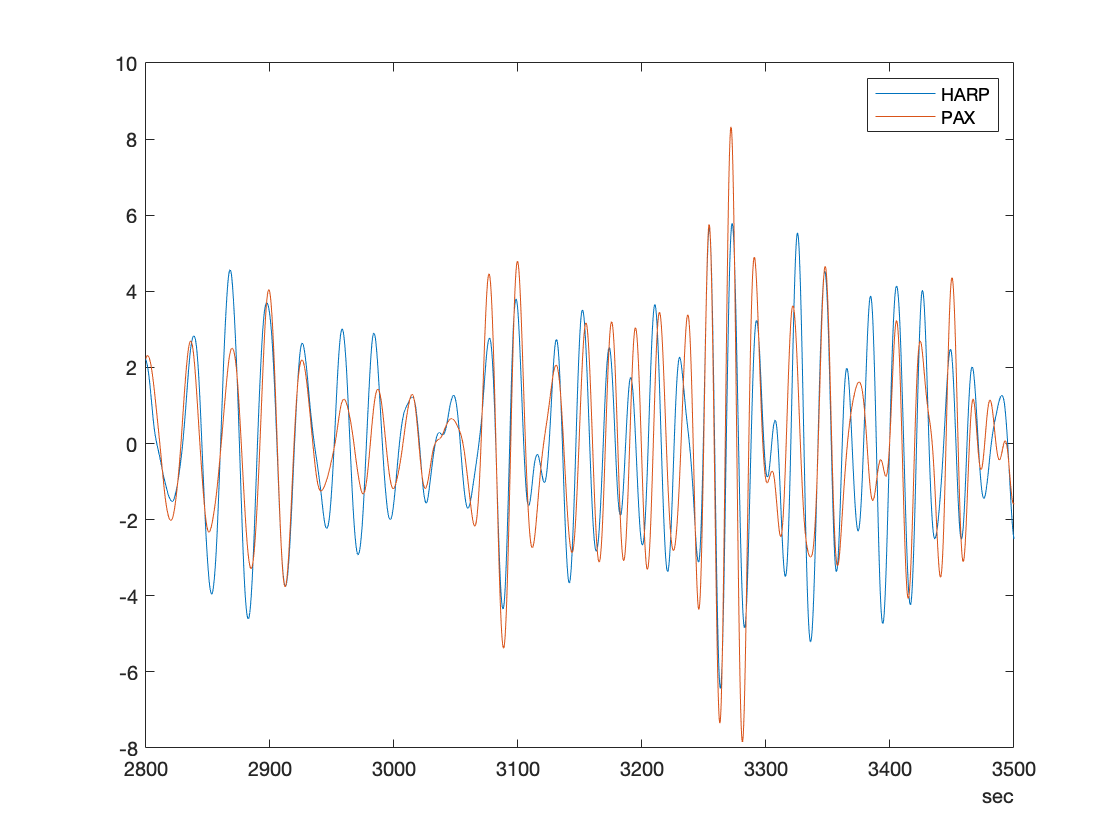

plot(harp.Time,harp.Signal)
hold on
plot(pax.Time,pax.Signal)
hold off
legend("HARP","PAX")
xlim(seconds([2800 3500]))

### **Spectral Analysis**

A dB scale is usually used to visualize power spectrums by calculating `10*log10(p)`, where *p* is the spectrum.

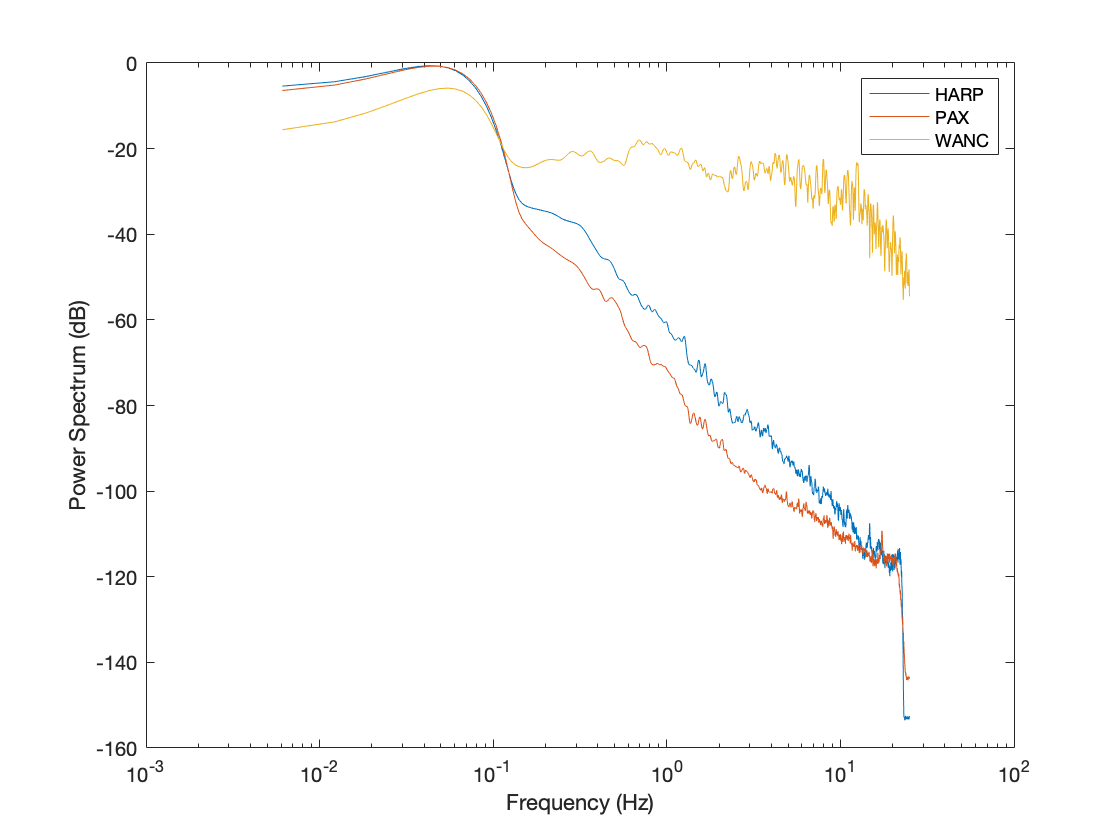

[p,f] = pspectrum(quakes);
semilogx(f,db(p,"power"))
legend("HARP","PAX","WANC")
xlabel("Frequency (Hz)")
ylabel("Power Spectrum (dB)")

Create a spectrogram with the `pspectrum` function by including the input `"spectrogram"`. 

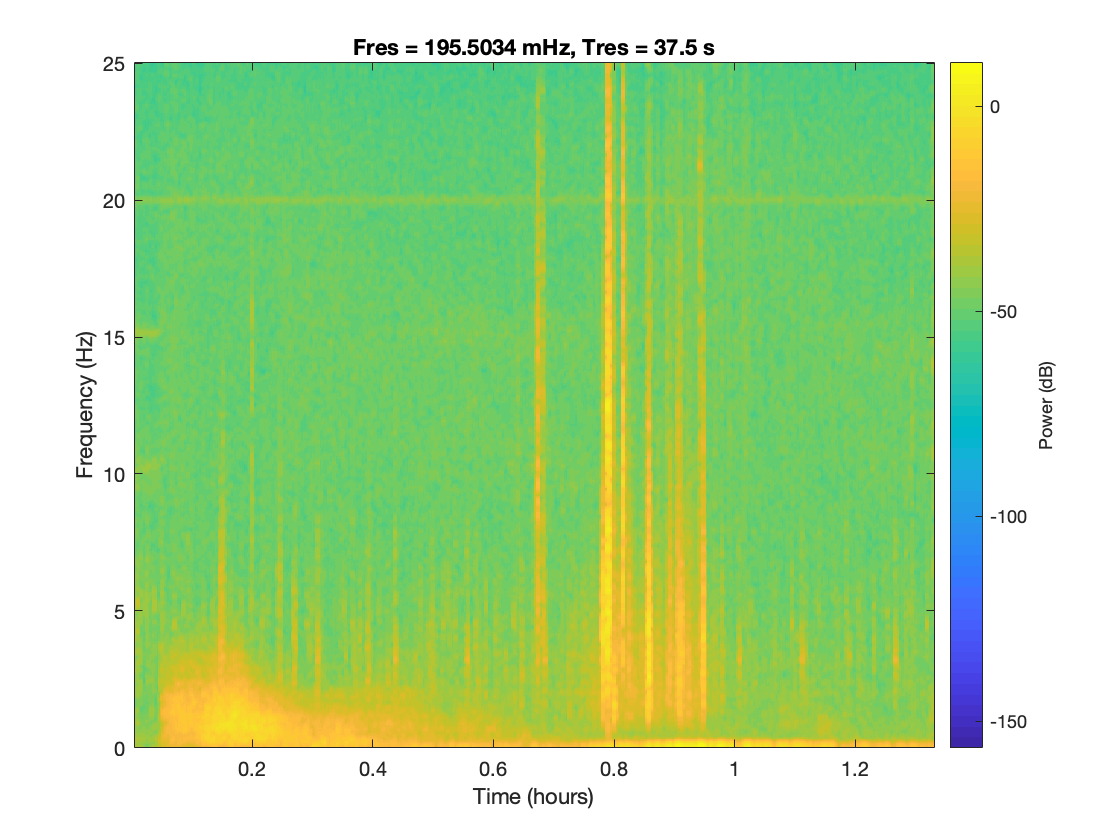

pspectrum(quakes.Signal_wanc,quakes.Time,"spectrogram")

Most tremors from local earthquakes contain frequencies between 2 Hz and 10 Hz. Remove frequencies that have low power using the `"MinThreshold"` option.

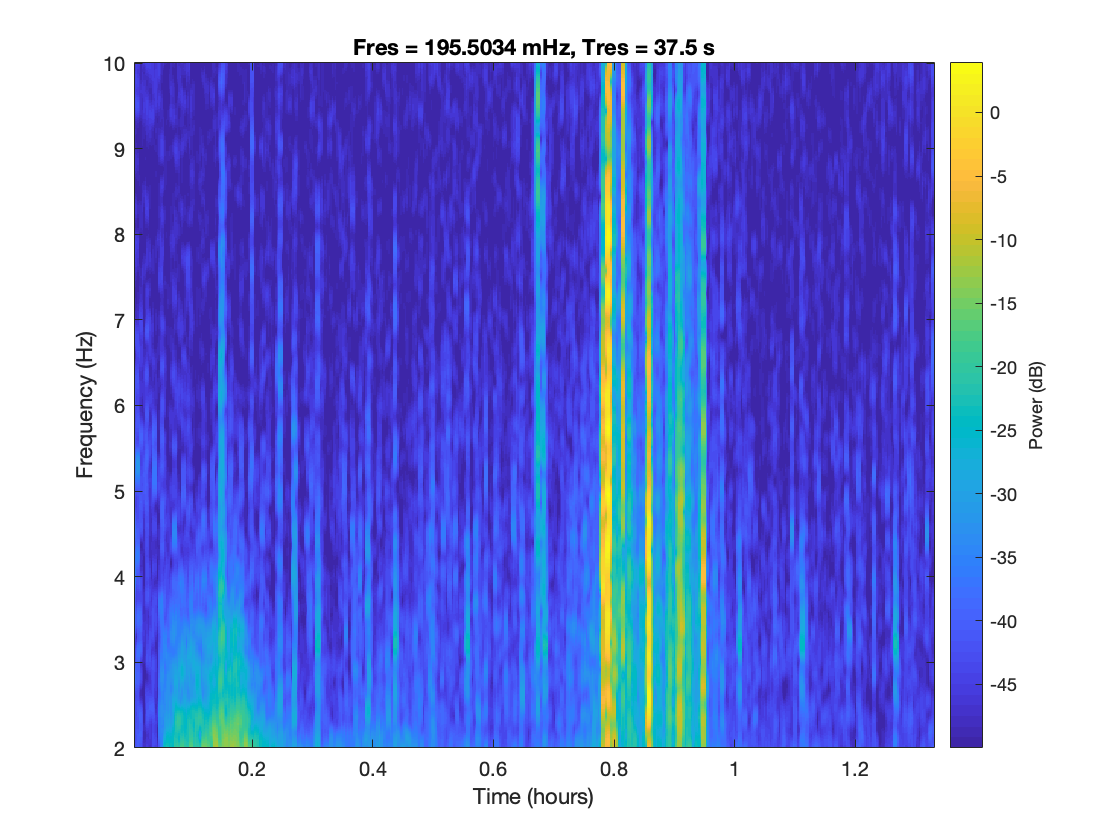

pspectrum(quakes.Signal_wanc,quakes.Time,"spectrogram",...
    "FrequencyLimits",[2 10],"MinThreshold",-50)

### Filtering

**Lowpass Filter**

The low frequencies and the high frequencies correspond to two different seismic events. We can extract the low frequency surface waves from the Indonesian earthquake and the seismic activity that it caused in Alaska.

Lowpass filter the Mount Wrangell signal at `0.1` Hz.

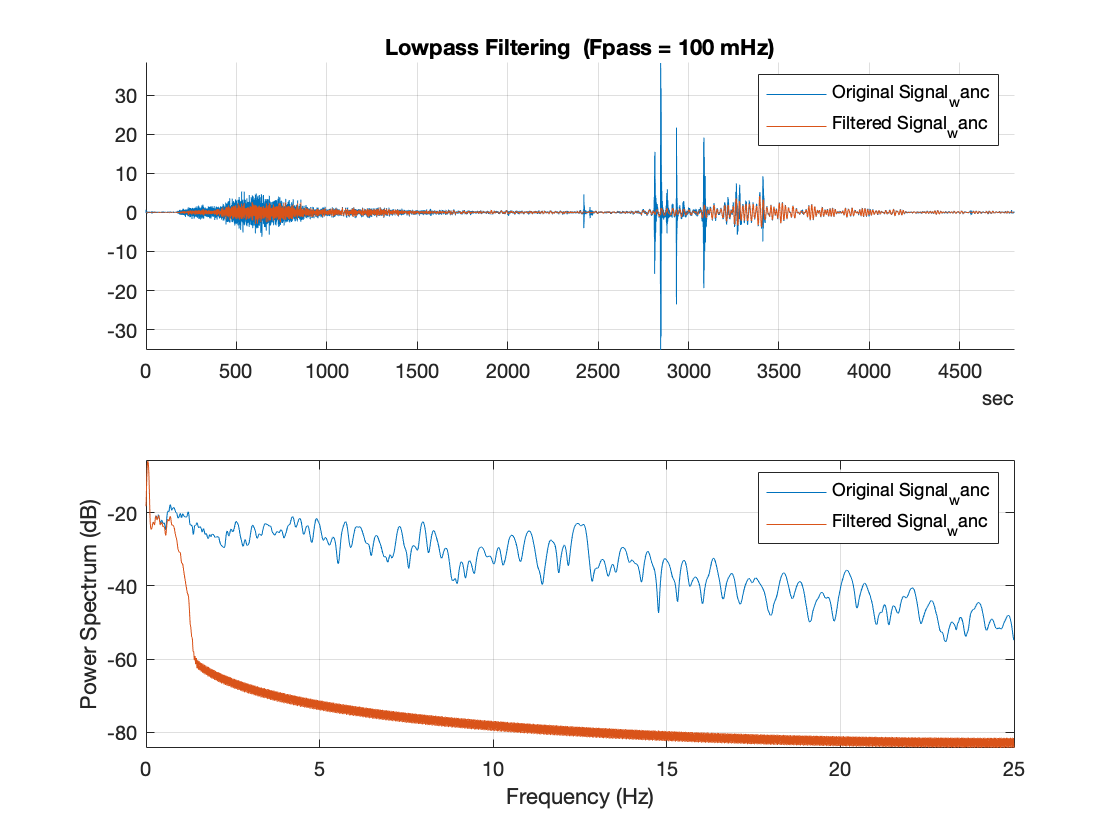

lowpass(quakes(:,"Signal_wanc"),0.1,"Steepness",0.95);

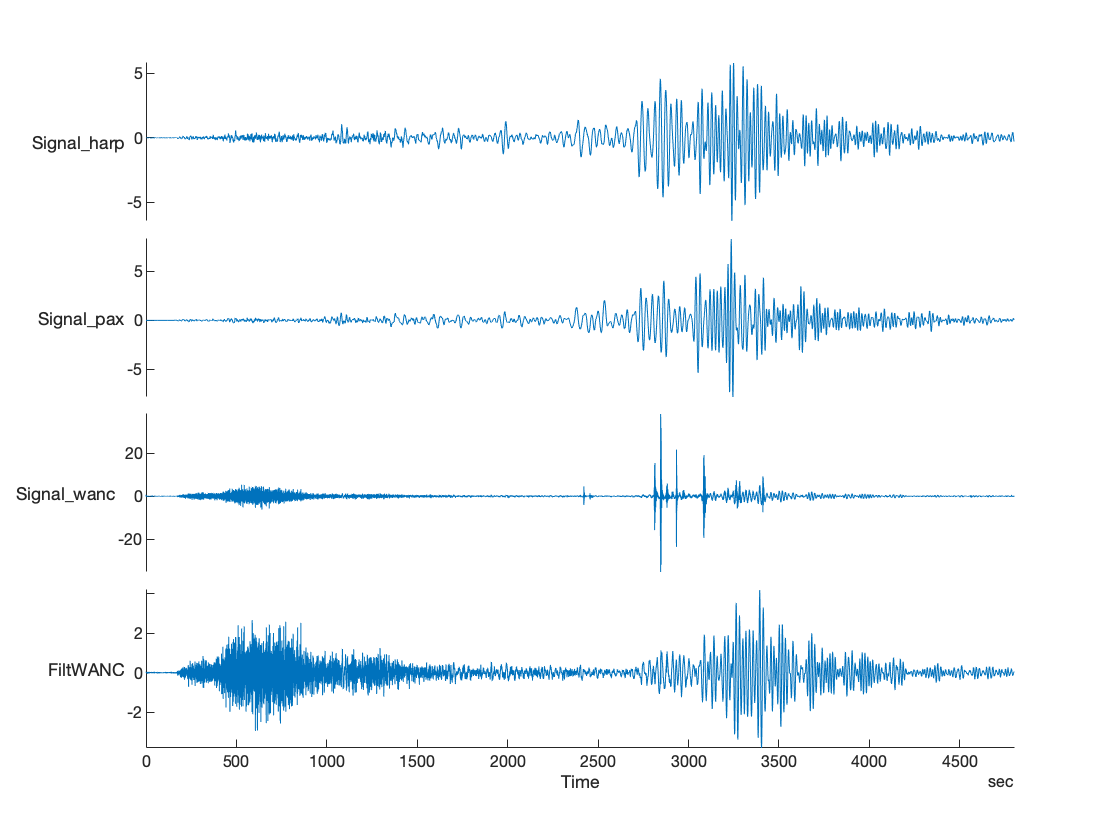

ans =   StackedLineChart with properties:

         SourceTable: [240000×4 timetable]
    DisplayVariables: {'Signal_harp'  'Signal_pax'  'Signal_wanc'  'FiltWANC'}
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties


lowWANC = lowpass(quakes(:,"Signal_wanc"),0.1,"Steepness",0.95);
quakes.FiltWANC = lowWANC.Signal_wanc;
figure
stackedplot(quakes)

**Bandpass Filter**

Get the high frequency content, which corresponds to the local earthquakes near Mount Wrangell. The frequency range of local earthquakes is 2 Hz to 10 Hz.

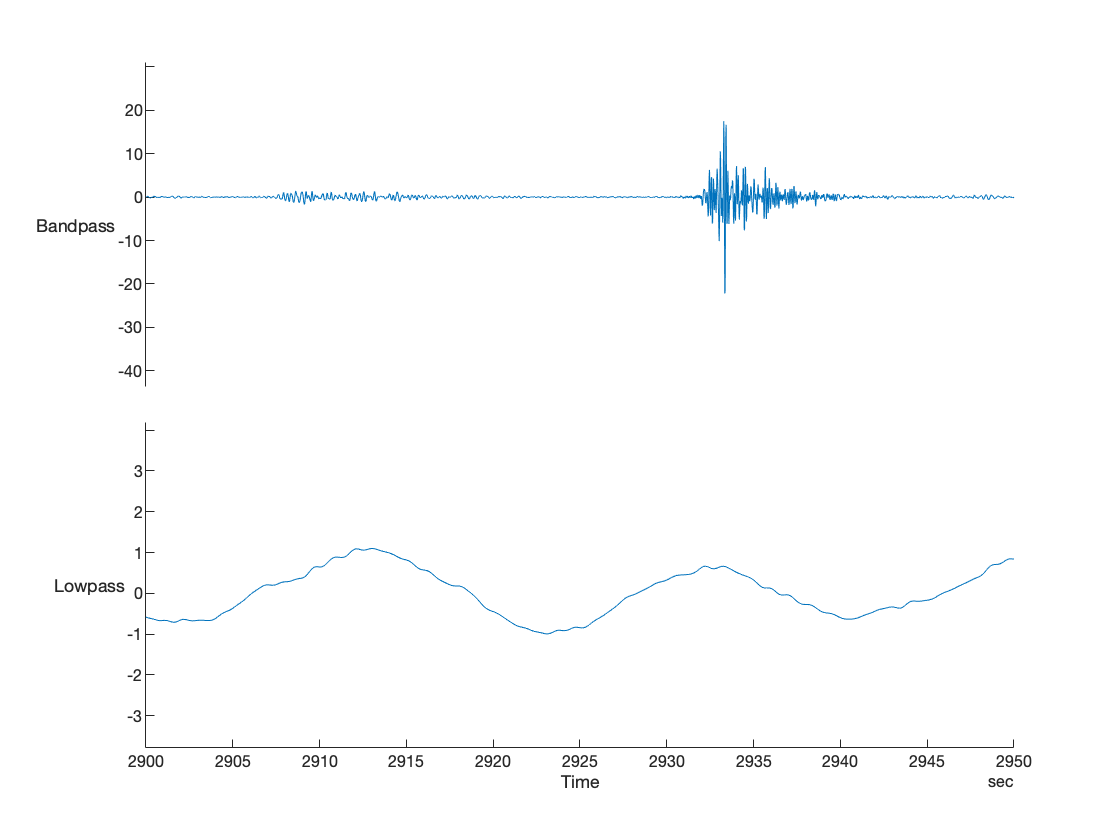

bandWANC = bandpass(quakes(:,"Signal_wanc"),[2 10]);
compfilt = timetable(bandWANC.Time,bandWANC.Signal_wanc,...
    quakes.FiltWANC,'VariableNames',["Bandpass" "Lowpass"]);
figure
stackedplot(compfilt);
xlim([seconds(2900) seconds(2950)])

The earth scientists thought that the earthquake in Sumatra triggered the earthquakes in Alaska. Using filtering, they were able to compare the low frequency and high frequency signals from the Mount Wrangell seismometer. This provided a rare opportunity for them to confirm the relationship between two distant earthquakes.

close all; clear; clc

## Audio Toolbox

[https://www.mathworks.com/products/audio.html](https://www.mathworks.com/products/audio.html)

Audio Toolbox™ provides tools for audio processing, speech analysis, and acoustic measurement. 

It provides tools and algorithms for:

- processing audio signals such as equalization and time stretching 

- estimating acoustic signal metrics such as loudness and sharpness 

- extracting audio features such as MFCC and pitch

- advanced machine learning models, including i-vectors

- pretrained deep learning networks, including VGGish and CREPE

- live algorithm testing

- impulse response measurement

- signal labeling

- ... ...

## DSP System Toolbox

[https://www.mathworks.com/products/dsp-system.html](https://www.mathworks.com/products/dsp-system.html)

DSP System Toolbox™ provides algorithms, apps, and scopes for designing, simulating, and analyzing signal processing systems in MATLAB and Simulink.

It provides tools and algorithms for:

- design and analyze FIR, IIR, multirate, multistage, and adaptive filters

- stream signals from variables, data files, and network devices for system development and verification

- dynamically visualize and measure streaming signals using the Time Scope, Spectrum Analyzer, and Logic Analyzer

- support C/C++ code generation for desktop prototyping and deployment to embedded processors

- support bit-accurate fixed-point modeling and HDL code generation from filters, FFT, IFFT, and other algorithm

- ... ...

#### **Visualize signals in frequency domain**

The **Spectrum Analyzer** System object displays the frequency spectrum of time-domain signals. This scope supports variable-size input, which allows the input frame size to change. Frame size is the first dimension of the input vector. The number of input channels must remain constant.

- Create the `dsp.SpectrumAnalyzer `object and call the object with arguments to display the spectra of signals in the Spectrum Analyzer.

- Set the `NumInputPorts` property to display multiple signals.

- `scope(signal1,signal2,...)` displays multiple signals in the spectrum analyzer. The signals must have the same frame length, but can vary in number of channels.

- Release system resources of a System object named `obj by` `release(obj).`

The right side of the spectrum analyzer shows the measurement panes (if enabled). The values shown in these panes match with the values shown in the last time step of the `data` variable. You can access the individual fields of `data` to obtain the various measurements programmatically.

Create a sine wave with a frequency of 100 Hz sampled at 1000 Hz, and another with a frequency of 240 Hz.

SampPerFrame = 1000;
Fs = 1000;
SW1 = dsp.SineWave('Frequency',100,'SampleRate',Fs,...
  'SamplesPerFrame',SampPerFrame);
SW2 = dsp.SineWave('Frequency',240,'SampleRate',Fs,...
  'SamplesPerFrame',SampPerFrame);

Generate ten seconds of the two sine waves with additive white noise in one-second intervals. Send the signals to a time scope and spectrum analyzer for display and measurement.

scope = dsp.SpectrumAnalyzer('NumInputPorts',2,'SampleRate',Fs);
tic;
while toc < 10
  sigData1 = SW1() + 0.05*randn(SampPerFrame,1);
  sigData2 = SW2() + 0.05*randn(SampPerFrame,1);
  scope(sigData1,sigData2);
end
release(scope)

Save the spectrum estimation displayed on a spectrum analyzer.

specTable = getSpectrumData(scope)

specTable = 1×3 table
    SimulationTime       Spectrum        FrequencyVector
    ______________    _______________    _______________

        [6896]        [1536×2 double]    [1536×1 double]


clear; clc

### **Extract voices from music signal**

**Implement a basic digital music synthesizer and use it to play a traditional song in a three-voice arrangement. **

Specify a sample rate of 2 kHz. 

% set up note frequencies
fs = 2e3;
t = 0:1/fs:0.3-1/fs;

l = [0 130.81 146.83 164.81 174.61 196.00 220 246.94];
m = [0 261.63 293.66 329.63 349.23 392.00 440 493.88];
h = [0 523.25 587.33 659.25 698.46 783.99 880 987.77];
note = @(f,g) [1 1 1]*sin(2*pi*[l(f) m(g) h(f)]'.*t);

Create a song.

% create a melody
mel1 = [2 0 2 1 2 0 2 1 2 4 5 6 5 4 2 1 6 0 0 0 6 0 0 0 6 0 0 0]+1;
mel2 = [2 0 0 0 2 0 0 0 2 0 5 0 5 0 2 0 6 0 6 5 6 5 4 5 6 6 6 6]+1;

song = [];
for kj = 1:length(mel1)
    song = [song note(mel1(kj),mel2(kj)) zeros(1,0.01*fs)];
end
song = song'/(max(abs(song))+0.1);

Play the song.

% play 
sound(song,fs)

Save the song as a timetable.

tune = timetable(seconds((0:length(song)-1)'/fs),song);

Open **Signal Analyzer** and drag the timetable from the **Workspace Browser** to the Signal table. 

Click **Display Grid** to create a two-by-two grid of displays. 

**Duplicate** three times to create three copies of the song. Rename the copies as `high`, `medium`, and `low` and display them in the three new displays.

Add a spectrum view  and click **Time-Frequency** to add a spectrogram view to each of the display. 

Preprocess each signal:

- Select the `high` signal by clicking its name in the Signal table. Select **Highpass** from the **Functions** gallery. In the **Function Parameters** panel, enter a passband frequency of `450` Hz and increase the steepness to `0.95`. Click **Apply**.

- Select the `medium` signal by clicking its name in the Signal table. Select **Bandpass** from the **Functions** gallery. In the **Function Parameters** panel, enter `230` Hz and `450` Hz as the lower and upper passband frequencies, respectively. Increase the steepness to `0.95`. Click **Apply**.

- Select the `low` signal by clicking its name in the Signal table. Select **Lowpass** from the **Functions** gallery. In the **Function Parameters** panel, enter a passband frequency of `230` Hz and increase the steepness to `0.95`. Click **Apply**.

Select the three filtered signals by clicking their **Name** column in the Signal table. 

On the **Analyzer** tab, click **Export** and save the signals to the current workspace.

Plot the spectra of the three signals.

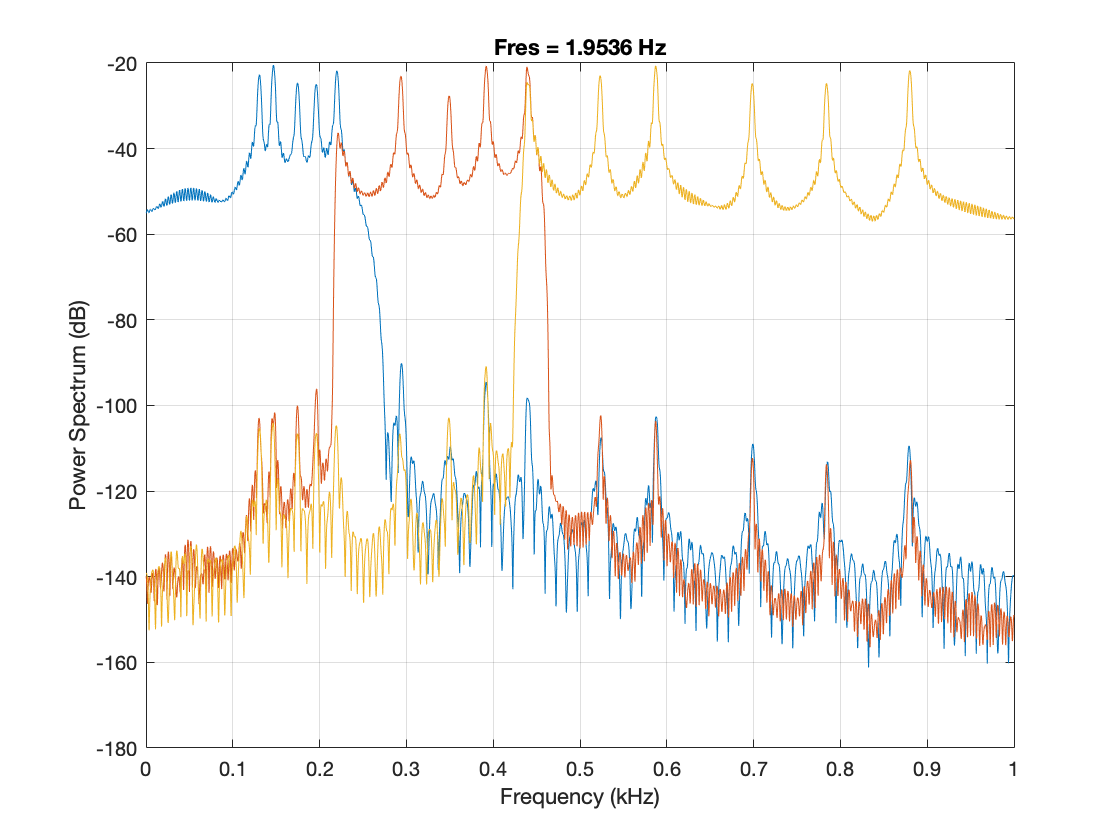

% plot the spectra after exporting to current workspace 
pspectrum(low)
hold on
pspectrum(medium)
pspectrum(high)
hold off

Hear the voices.

% hear the low, medium, and high signals
sound(low.low,fs), pause(10), sound(medium.medium,fs), pause(10), sound(high.high,fs)